# Milling and Welding Todo

See the video: [https://youtu.be/cVZWm9ORY30](https://youtu.be/cVZWm9ORY30)

As you can see in the video a Robot Arm perform three task. Only two tasks are shown: 

- Make a hole in a cylinder by drilling it. Observe that the tool mantain the same orientation during the drilling task.

- Insertion of a smaller cylinder not recorder here. 

- Welding the two cylinder. Observe that the tool always form a 45º with respect to  red cylinder axis

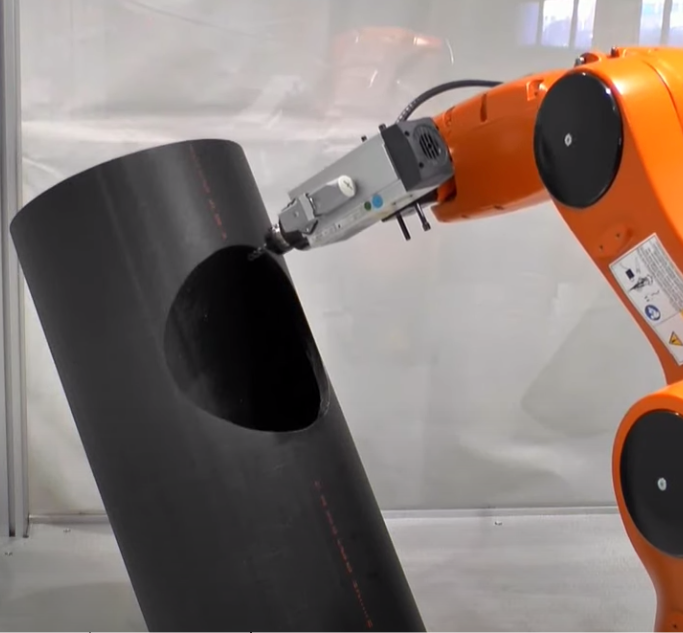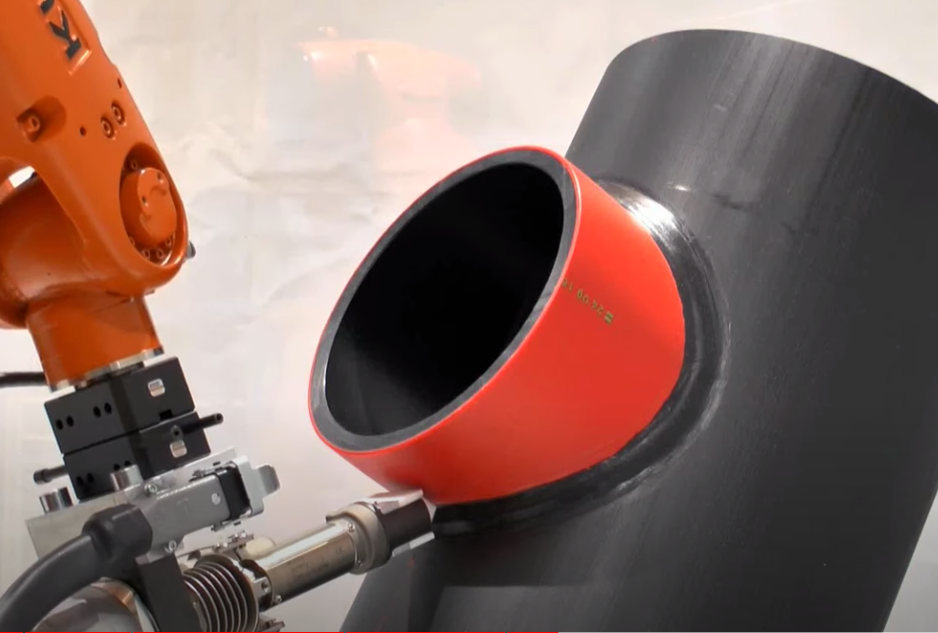

## Sketching your ideas

Conceptualize the problem. Add a sketch and make some small scripts

## Environment preparation

### Loading and robot setup

clear;
close all;
clf
load('F_V_cylinder.mat');
radius = 0.20;
n = 200;
mdl_puma560
% p560.base = transl(-0.1, 0, 0);
p560.tool = transl(0,0,0.15);
p560.plot(qn, 'zoom', 2.5, 'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1], 'view', [20 20]);
axis equal
hold on

### Creating the cylinders for drilling and welding

% first we create the cylinder for the drilling task
Cy_scale = 0.25;
CY_pose = transl([-0.3 0.3 -0.35]) * troty(-pi/6) * trotx(-pi/6);
V_cy_drill = CY_pose * [Cy_scale .* V_cy'; ones(1, length(V_cy))];
FVsPlot(F_cy,V_cy_drill(1:3,:)',[0 1 0])
% we then create the second cylinder for the welding task
Cy_scale2 = 0.25;
CY_pose2 = transl([0.3 0.3 -0.35]) * troty(pi/6) * trotx(-pi/6);
V_cy_drill2 = CY_pose2 * [Cy_scale2 .* V_cy'; ones(1,length(V_cy))];
FVsPlot(F_cy, V_cy_drill2(1:3, :)', [0 1 0])

## Drilling task

### Getting the cylinder pose

D_h_c = CY_pose * transl(0,0,0.6) * trotx(-pi/2) * troty(-pi/4) * transl(0,0,-0.25);

### Performing the drilling

We perform the drilling by doing a full rotation over the z axis in n steps while drawing the contour of the radius. Note that in this action we are not changing the pose of our actuator.

n=60
for i=1:n
Drill_Pose(:,:,i)= D_h_c*trotz(2*pi*i/n)*transl(radius, 0,0);
end

n = 60

cir=transl(Drill_Pose)';
hold on
plot3(cir(1,:), cir(2,:), cir(3,:),'r','LineWidth',3);
%axis([-1.5 1.5 -1.5 1.5 -0.5 1])
axis equal
trplot(Drill_Pose(:,:,1), 'length',0.2, 'arrow')
trplot(Drill_Pose(:,:,15), 'length',0.2, 'arrow')
trplot(Drill_Pose(:,:,30), 'length',0.2, 'arrow')
trplot(Drill_Pose(:,:,45), 'length',0.2, 'arrow')

### Recording a video of the drilling action

%Q = p560.ikine6s(Drill_Pose, 'run');
%p560.plot(Q, 'view', [20 20], 'zoom', 1.5, 'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1], ...

%    'trail', '-', 'jaxes', 'zoom', 2, 'movie', 'Puma_drilling_task.mp4')

## Welding task

### Getting the cylinder pose

W_h_c = CY_pose2 * transl(0,0,0.6) * trotx(pi/2) * troty(-pi/4) * transl(0,0,0.26);

### Performing the welding

#### Intent 1: hardcoding les poses i peli

We perform the welding 

r=0.2;
t=0:pi/16:2*pi;
cp0=[r*cos(t);r*sin(t);abs(r*cos(t));ones(1,length(t))];

% Translation of the welding
T0 = transl(0.5, 0.5, 0.2) * trotz(pi/4) * troty(-pi/4) * transl(0, 0, -0.1);
cp1 = T0 * cp0;

% Draws the welding
scatter3(cp1(1,:), cp1(2,:), cp1(3,:),'.', 'm', 'LineWidth', 2)

% Reference frame
trplot(T0, 'length', 0.2, 'arrow')

T1 = T0 * transl(0, 0.2, 0) * troty(pi) * trotx(pi/4);
trplot(T1, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T2 = T0 * transl(-0.141421, 0.141421, 0.141421) * troty(pi) * trotz(-pi/4) * trotx(pi/4);
trplot(T2, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T3 = T0 * transl(-0.2, 0, 0.2) * troty(pi) * trotz(-pi/2) * trotx(pi/4);
trplot(T3, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T4 = T0 * transl(-0.141421, -0.141421, 0.141421) * trotz(-pi/4) * trotx(-3*pi/4);
trplot(T4, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T5 = T0 * transl(0, -0.2, 0) * trotx(-3*pi/4);
trplot(T5, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T6 = T0 * transl(0.141421, -0.141421, 0.141421) * trotz(pi/4) * trotx(-3*pi/4);
trplot(T6, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T7 = T0 * transl(0.2, 0, 0.2) * troty(pi) * trotz(pi/2) * trotx(pi/4);
trplot(T7, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T8 = T0 * transl(0.141421, 0.141421, 0.141421) * troty(pi) * trotz(pi/4) * trotx(pi/4);
trplot(T8, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

Welding_Pose(:,:,1) = T1;
Welding_Pose(:,:,2) = T2;
Welding_Pose(:,:,3) = T3;
Welding_Pose(:,:,4) = T4;
Welding_Pose(:,:,5) = T5;

Welding_Pose(:,:,6) = T6;
Welding_Pose(:,:,7) = T7;
Welding_Pose(:,:,8) = T8;


### Recording a video of the Welding

%Q = p560.ikine6s(Welding_Pose, 'run');
%p560.plot(Q,'view',[150 45], 'zoom',1.5,'workspace', [-1 0.5 -0.5 0.5 -1 1])

%Q = p560.ikine6s(Welding_Pose, 'run');
%p560.plot( Q,'view',[150 45], 'zoom',1.5,'workspace', [-1 0.5 -0.5 0.5 -1 1],...
%             'trail','-','jaxes','zoom',2,'movie','Puma_welding_task.mp4')

#### Intent 2: loop sobre la forma de cp0, tinc la teoria que estem rotant de més, si ja rotem al computar cp1 potser no caldria re-rotar la pose??

%r=0.2;
%t=0:pi/16:2*pi;
%cp0=[r*cos(t);r*sin(t);abs(r*cos(t));ones(1,length(t))];

% Translation of the welding
%T0 = transl(0.5, 0.5, 0.2) * trotz(pi/4) * troty(-pi/4) * transl(0, 0, -0.1);
%cp1 = T0 * cp0;
% Define rotation matrix for rotating z-axis by 45 degrees
%R = trotz(pi/4) * troty(-pi/4);

% Initialize Welding_Pose matrix
%num_points = size(cp1, 2);
%Welding_Pose = zeros(4, 4, num_points);


% Loop through each point and calculate the welding pose
%for i=1:num_points
    % Calculate position of point in welding frame
    %point_pos = cp1(:, i);
    %point_pos(3) = -point_pos(3);
    %point_pose = eye(4);
    %point_pose(1:4, 4) = point_pos;
    
    % Calculate orientation of welding tool
    %cyl_z = W_h_c(1:3, 3);
    %weld_z = R(1:3, 1:3) * cyl_z;
    %rot_axis = cross(cyl_z, weld_z);
    %rot_axis = rot_axis / norm(rot_axis);
    %rot_angle = acos(dot(cyl_z, weld_z));
    %weld_rot = angvec2tr(rot_angle, rot_axis);

    % Combine position and orientation into welding pose
    %welding_pose = point_pose * weld_rot;

    % Store welding pose in Welding_Pose matrix
    %Welding_Pose(:, :, i) = welding_pose;
%end

% plot of the poses
%for i=1:num_points
    %trplot(Welding_Pose(:,:,i), 'length', r/2, 'arrow', 'width', 0.5, 'color','r')
%end

%Q = p560.ikine6s(Welding_Pose, 'run');
%p560.plot( Q,'view',[150 45], 'zoom',1.5,'workspace', [-1 0.5 -0.5 0.5 -1 1],...
             %'trail','-','jaxes','zoom',2,'movie','test_Puma_welding_task.mp4')

#### Intent 3: passant del cilindre i anant directe als angles

%cp1 = transl(0.6,0.3,0.0)*trotz(3*pi/4)*trotx(-pi/4)
%r=0.20; % Tube radius
%t=0:pi/16:2*pi; % Scan variable
%n = 60;

%signus = 1;
%for i=1:n

    %beta = 2*pi*i/n;
    %mov = sqrt(r^2*(1-cos(pi/2-beta)^2));

    %hip = (r-mov)/cos(pi/4);
    %if i==n/4

Error using Animate
MP4 creation not supported by MATLAB on this platform

Error in SerialLink/plot (line 264)
        robot.movie = Animate(opt.movie);

        %signus = -1;
    %elseif i==(n/2+n/4)
        %signus = 1;
    %end
    %Welding_Pose_III(:,:,i) = cp1*transl(-r*cos(pi/2-beta), signus*mov, r-sqrt(hip^2-(r-mov)^2))*troty(-pi)*trotz(-beta)*trotx(pi/4);
%end

%Q = p560.ikine6s(Welding_Pose_III, 'run');

%p560.plot(Q,'view',[20 20], 'zoom',1.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],...
    %'trail','-','jaxes','zoom',2)

## Annex section

### Some help for inspiration

Visit in that order the folder: Hints_Cues

1_Puma_doing_task_example.mlx

2_Puma_doing_task.mp4

3_Drilling_Solution.mlx

4_Puma_doing_drilling_task.avi

5_Puma_doing_welding_task.avi

6_Hint_cue_for welding task.fig

### Util functions

function T_b_a=FVsPlot(F,V,color)
patch('Faces',F,'Vertices',V,'FaceColor',color, ...
         'FaceAlpha',0.8,...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

grid on
xlabel 'X [mm]'
ylabel 'Y [mm]'
zlabel 'Z [mm]'
axis equal
end